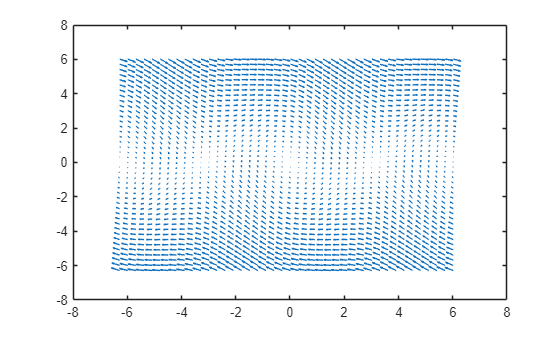

clear
clc
close all

load ../dynamics.mat

% substitute in some values 
% looking at autonomous system dynamics, so set both torques equal to zero
% NOTE NEED TO GO THROUGH AND FIGURE OUT WHICH "BASE VARIABLES" WE CAN USE TO SOLVE FOR OTHER VARIABLES (I.E., J0HAT) 
subs_array = [ ...
              theta_1      0
              theta_1_dot  0
              % theta_2      0
              % theta_2_dot  0
              J_0_hat      0.1
              J_1_hat      0.1
              J_2_hat      0.2
              m_1          0.1
              m_2          0.1
              L_1          0.1
              L_2          0.1
              l_1          0.5
              l_2          0.5
              b_1          0.1
              b_2          0.1
              tau_1        0
              tau_2        0
              g            9.81 ...
             ];


theta_1_ddot_auto = subs( ...
    theta_1_ddot, subs_array(:,1), subs_array(:,2));
theta_2_ddot_auto = subs( ...
    theta_2_ddot, subs_array(:,1), subs_array(:,2));



% verify behavior of planar system (i.e., let theta_2 = theta_2_dot = 0)

% x1 := theta_2, x2 := theta_2_dot
t2dd = matlabFunction( theta_2_ddot_auto, 'Vars', [theta_2 theta_2_dot]);

% [X1, X2] = meshgrid( -3*pi/4 : 0.3 : 3*pi/4 );
[X1, X2] = meshgrid( -2*pi : 0.3 : 2*pi );

X1DOT = X2;
X2DOT = t2dd( X1, X2 );

figure
quiver( X1, X2, X1DOT, X2DOT, 1 )